# Task 7: The spin-1/2 Heisenberg square under a magnetic field

We now take the system of the previous task and add an external magnetic field along the ${\bf z}$-axis. The Hamiltonian of this problem is described by the Hamiltonian


$$\mathcal{H} = J ({\bf S}_1 \cdot {\bf S}_2+{\bf S}_2 \cdot {\bf S}_3+{\bf S}_3 \cdot {\bf S}_4+{\bf S}_4 \cdot {\bf S}_1) -\gamma B S_z\,.$$


In the following we set $J=1$.

# Subtask a

Write a few lines of code that deliver the matrix representation of $\mathcal{H}$ in the `product-$S_z$ basis' for $\gamma B=1$. Solve the Schroedinger equation to obtain the energy eigenvalues and the corresponding eigenstates. 

%Values used in Hamitonian from task 6
GammaB = 1;
Hamiltonian = J*(S1x*S2x + S1y*S2y + S1z*S2z + S2x*S3x + S2y*S3y + S2z*S3z + S3x*S4x + S3y*S4y + S3z*S4z + S4x*S1x + S4y*S1y + S4z*S1z) - GammaB * Sz

Hamiltonian =    -1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -1.0000    0.5000         0         0         0         0         0    0.5000         0         0         0         0         0         0         0
         0    0.5000   -1.0000         0    0.5000         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    0.5000         0         0         0         0    0.5000         0         0         0         0         0
         0         0    0.5000         0   -1.0000         0         0         0    0.5000         0         0         0         0         0         0         0
         0         0         0    0.5000         0   -1.0000    0.5000         0         0    0.5000         0         0    0.5000         0         0         0
         0         0

Energy = eig(Hamiltonian)

Energy =    -2.0000
   -2.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000


[V,D] = eig(Hamiltonian)

V =          0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000   -0.0000    0.0600         0    0.1590   -0.6864    0.2049         0   -0.1571   -0.3991   -0.1552   -0.0000   -0.0000         0         0         0
   -0.5000    0.0000   -0.6196         0    0.3399    0.0246    0.2049         0   -0.1571   -0.3991   -0.1552   -0.0000   -0.0000         0         0         0
   -0.0000   -0.2887   -0.0000         0   -0.0000   -0.0000    0.4030         0    0.7156   -0.1613    0.2224    0.3888    0.1246         0         0         0
    0.5000   -0.0000   -0.0600         0   -0.1590    0.6864    0.2049         0   -0.1571   -0.3991   -0.1552   -0.0000   -0.0000         0         0         0
    0.0000    0.5774    0.3355         0    0.5993    0.1681    0.0000         0   -0.0000    0.0000   -0.0000    0.3888    0.1246         0         0         0
   -0.0000   -0.2887    0.0000

D =    -2.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -2.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0   -1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   -1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0   -1.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0   -1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0

EigState1 = V(:, 1)

EigState1 =          0
    0.5000
   -0.5000
   -0.0000
    0.5000
    0.0000
   -0.0000
    0.0000
   -0.5000
   -0.0000


Energy1 = Energy(1)

Energy1 = -2.0000

EigState2 = V(:, 2)

EigState2 =          0
   -0.0000
    0.0000
   -0.2887
   -0.0000
    0.5774
   -0.2887
   -0.0000
    0.0000
   -0.2887


Energy2 = Energy(2)

Energy2 = -2

EigState3 = V(:, 3)

EigState3 =          0
    0.0600
   -0.6196
   -0.0000
   -0.0600
    0.3355
    0.0000
   -0.0000
    0.6196
    0.0000


Energy3 = Energy(3)

Energy3 = -1.0000

EigState4 = V(:, 4)

EigState4 =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


Energy4 = Energy(4)

Energy4 = -1.0000

EigState5 = V(:, 5)

EigState5 =          0
    0.1590
    0.3399
   -0.0000
   -0.1590
    0.5993
   -0.0000
   -0.0000
   -0.3399
    0.0000


Energy5 = Energy(5)

Energy5 = -1

EigState6 = V(:, 6)

EigState6 =          0
   -0.6864
    0.0246
   -0.0000
    0.6864
    0.1681
    0.0000
   -0.0000
   -0.0246
    0.0000


Energy6 = Energy(6)

Energy6 = -1.0000

EigState7 = V(:, 7)

EigState7 =          0
    0.2049
    0.2049
    0.4030
    0.2049
    0.0000
    0.3471
    0.0000
    0.2049
   -0.7410


Energy7 = Energy(7)

Energy7 = -5.1639e-16

EigState8 = V(:, 8)

EigState8 =          0
         0
         0
         0
         0
         0
         0
   -0.5000
         0
         0


Energy8 = Energy(8)

Energy8 = -1.3928e-16

EigState9 = V(:, 9)

EigState9 =          0
   -0.1571
   -0.1571
    0.7156
   -0.1571
   -0.0000
   -0.6190
    0.0000
   -0.1571
   -0.0742


Energy9 = Energy(9)

Energy9 = -1.3332e-16

EigState10 = V(:, 10)

EigState10 =          0
   -0.3991
   -0.3991
   -0.1613
   -0.3991
    0.0000
    0.2568
   -0.0000
   -0.3991
   -0.4127


Energy10 = Energy(10)

Energy10 = 9.5410e-18

EigState11 = V(:, 11)

EigState11 =          0
   -0.1552
   -0.1552
    0.2224
   -0.1552
   -0.0000
    0.4248
    0.0000
   -0.1552
    0.1583


Energy11 = Energy(11)

Energy11 = 2.8362e-16

EigState12 = V(:, 12)

EigState12 =          0
   -0.0000
   -0.0000
    0.3888
   -0.0000
    0.3888
    0.3888
   -0.2158
   -0.0000
    0.3888


Energy12 = Energy(12)

Energy12 = 1.0000

EigState13 = V(:, 13)

EigState13 =          0
   -0.0000
   -0.0000
    0.1246
   -0.0000
    0.1246
    0.1246
    0.6734
   -0.0000
    0.1246


Energy13 = Energy(13)

Energy13 = 1

EigState14 = V(:, 14)

EigState14 =          0
         0
         0
         0
         0
         0
         0
   -0.0000
         0
         0


Energy14 = Energy(14)

Energy14 = 1

EigState15 = V(:, 15)

EigState15 =          0
         0
         0
         0
         0
         0
         0
   -0.5000
         0
         0


Energy15 = Energy(15)

Energy15 = 2.0000

EigState16 = V(:, 16)

EigState16 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Energy16 = Energy(16)

Energy16 = 3

# Subtask b

Plot the energy spectrum vs $\gamma B$, in the range $\gamma B \in [-5,5]$.

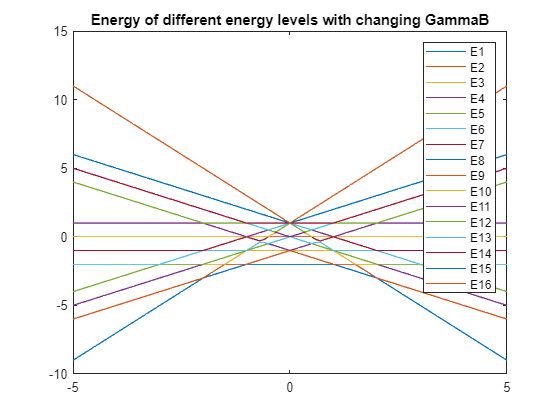

E1 = [];
E2 = [];
E3 = [];
E4 = [];
E5 = [];
E6 = [];
E7 = [];
E8 = [];
E9 = [];
E10 = [];
E11 = [];
E12 = [];
E13 = [];
E14 = [];
E15 = [];
E16 = [];


for GammaB = -5:0.1:5;
    Hamiltonian = (J*(S1x*S2x + S1y*S2y + S1z*S2z + S2x*S3x + S2y*S3y + S2z*S3z + S3x*S4x + S3y*S4y + S3z*S4z + S4x*S1x + S4y*S1y + S4z*S1z) - GammaB * Sz);
    Energy = eig(Hamiltonian);
    E1 = [E1 Energy(1)];
    E2 = [E2 Energy(2)];
    E3 = [E3 Energy(3)];
    E4 = [E4 Energy(4)];
    E5 = [E5 Energy(5)];
    E6 = [E6 Energy(6)];
    E7 = [E7 Energy(7)];
    E8 = [E8 Energy(8)];
    E9 = [E9 Energy(9)];
    E10 = [E10 Energy(10)];
    E11 = [E11 Energy(11)];
    E12 = [E12 Energy(12)];
    E13 = [E13 Energy(13)];
    E14 = [E14 Energy(14)];
    E15 = [E15 Energy(15)];
    E16 = [E16 Energy(16)];
end;
y = -5:0.1:5;
plot(y,E1)
hold on
plot(y,E2)
hold on
plot(y,E3)
hold on
plot(y,E4)
hold on
plot(y,E5)
hold on
plot(y,E6)
hold on
plot(y,E7)
hold on
plot(y,E8)
hold on
plot(y,E9)
hold on
plot(y,E10)
hold on
plot(y,E11)
hold on
plot(y,E12)
hold on
plot(y,E13)
hold on
plot(y,E14)
hold on
plot(y,E15)
hold on
plot(y,E16)
hold on

legend('E1','E2','E3','E4','E5','E6','E7','E8','E9','E10','E11','E12','E13','E14','E15','E16')
title("Energy of different energy levels with changing GammaB")
hold off

# Subtask c

Plot the $\textbf{ground state}$ quantum mechanical expectation value of the operator $S_z$ vs $\gamma B$, in the range $\gamma B \in [-5,5]$. 

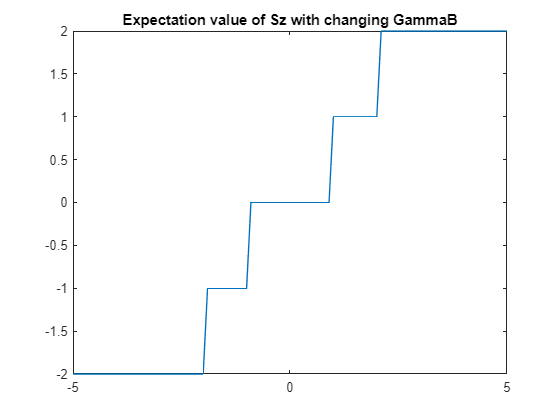

ExpectationSz = [];
for GammaB = -5:0.1:5;
    Hamiltonian = J*(S1x*S2x + S1y*S2y + S1z*S2z + S2x*S3x + S2y*S3y + S2z*S3z + S3x*S4x + S3y*S4y + S3z*S4z + S4x*S1x + S4y*S1y + S4z*S1z) - GammaB * Sz;
    [V,D] = eig(Hamiltonian);
    EigState1 = V(:,1);
    E1ExpectationSz = EigState1' * Sz * EigState1;
    ExpectationSz = [ExpectationSz E1ExpectationSz];
end
ExpectationSz;
x = -5:0.1:5;
plot(x,ExpectationSz)
title("Expectation value of Sz with changing GammaB")